clc; clear; close all
Kf=0.102; %forward rate
Kr=0.0102; %reverse rate
K2=0.5; % Product formation rate
e0=10; % Enzyme concetration
Km=5; % Michaelis Constant
V_max=5 % Maximum Velocity

V_max = 5

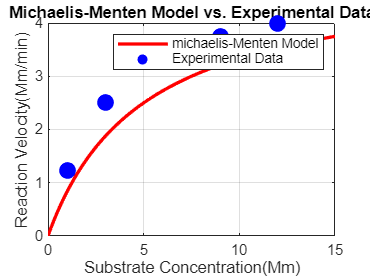


%Defining subatrate concentrations
S0=[1,3,9,12]; %Initial Substrate
V0_data=[1.23,2.5,3.75,4.0]; %experimental Velocities

%Michaelis-Menten equation
S_Range=linspace(0,15,100);
V0_mm=(V_max.*S_Range)./ (Km+S_Range);

%Plotted data Graph and Model
figure;
plot(S_Range, V0_mm, 'r-','Linewidth', 2); hold on
scatter(S0,V0_data, 100,'B','filled');
xlabel('Substrate Concentration(Mm)');
ylabel('Reaction Velocity(Mm/min)');
legend('michaelis-Menten Model', 'Experimental Data');
title('Michaelis-Menten Model vs. Experimental Data');
grid on